# Exercise: Pointing Knowledge Analysis

An observation satellite has the following knowledge requirements (assume ergodicity):

- Absolute knowledge error (AKE): $\sigma_{\textrm{ABS}} \le 1\;\arcsec$

- Relative knowledge error (RKE) over a 5s time window: $\sigma_{\textrm{WV}} \le 0\ldotp 5\;\arcsec$

The satellite shall be equipped with a JOP Astro APS 3 star tracker (STR). Is this STR accurate enough or is a gyro-stellar estimator (GSE) necessary? For the latter, an Astrix 120 gyroscope would be used.

For the STR, take the following assumptions and values from the datasheet:

- Total error 2.4 arcsec across boresight, 20 arcsec around boresight ($3\sigma \;$)

- 10 Hz sampling rate

- Assume that the noise can be considered as band-limited white noise (BLWN).

- Assume that you can freely choose the STR orientation.

For the gyro, assume the following values from the datasheet:

- Angular random walk coefficient: $0\ldotp 0016\degree /\sqrt{\mathrm{h}}$ ($1\sigma \;$)

- Bias instability/flicker rate coefficient: 0.01°/h ($3\sigma \;$)

% Clean Up
clear
close all
clc

% Create frequency grid for evaluations
fVec = logspace(-5,1,1001)'; % [Hz]

% Conversion rad <-> arcsec
rad2arcsec = 180/pi * 3600;
arcsec2rad = pi/180 * (1/3600);

% Knowledge requirements (for later)
eABSreq = 1 * arcsec2rad;	  % [rad]
eWVreq = 0.5 * arcsec2rad;	% [rad]

Note: Always take care with the units! Hertz are more intuitive for frequencies, but some operations strictly require the angular frequency in rad/s. It might help to distinguish between the symbol/variable name f (in Hertz) and $\omega \;$(in rad/s).

## STR Data

The STR's standard deviation is directly converted to radians. The power spectral density (PSD) of BLWN is constant up to the Nyquist frequency $1/\left(2\Delta t\right)$ and zero afterwards:


$$S_{\mathrm{STR}}(f) = \begin{cases}	2\,\sigma^2_{\mathrm{STR}}\,\Delta t	&	f \leq 1/(2\,\Delta t)	\\
		0	&	f>1/(2\,\Delta t)	\end{cases}$$


Throughout this exercise, single-sided PSDs are assumed, hence the factor 2. Applying the Wiener-Khinchin theorem yields as expected:


$$\sigma^2_{\mathrm{STR}} =\frac{1}{2\pi} \int_{0}^{\infty} S_{\mathrm{STR}}(\omega)\,\mathrm{d}\omega$$


strStd = 2.4 * pi/(180*3600); % [rad]
strDt = 0.1;		% [s]

strPsd = zeros(size(fVec));
strPsd(fVec<1/(2*strDt)) = 2 * strStd^2 * strDt;  %

strPsdInt = dot(gradient(fVec),strPsd);
strStdApprox = sqrt(strPsdInt);

fprintf('Specified STR std:             %g arcsec\nApproximated STR std from PSD: %g arcsec',strStd*rad2arcsec,strStdApprox*rad2arcsec);

Specified STR std:             2.4 arcsec
Approximated STR std from PSD: 2.39459 arcsec

## Knowledge Analysis: STR Only

If only the STR is used, its accuracy directly corresponds to the AKE. Obviously, the STR is accurate enough to fulfill the AKE requirement of 1 arcsec:

strAbs = strStd;  % [rad]
fprintf('STR ABS knowl. error:  %g arcsec\nABS knowl. error req.: %g arcsec',strAbs * rad2arcsec,eABSreq * rad2arcsec);

STR ABS knowl. error:  2.4 arcsec
ABS knowl. error req.: 1 arcsec

The RKE is evaluated by integrating the STR's noise PSD weighted by the WV metric:


$$\sigma^2_{\mathrm{RKE}} = \frac{1}{2\pi} \int_{0}^{\infty} F_{\mathrm{WV}}(\omega\Delta t)\,S_{\mathrm{STR}}(\omega)\,\mathrm{d}\omega = \int_{0}^{\infty} F_{\mathrm{WV}}(f, \Delta t)\,S_{\mathrm{STR}}(f)\,\mathrm{d}f$$


with


$$F_{\mathrm{WV}}(\omega\,\Delta t)= 1 - \frac{ \sin^2\left(\omega \Delta t / 2\right) }{\left( \omega \Delta t /2 \right)^2}$$


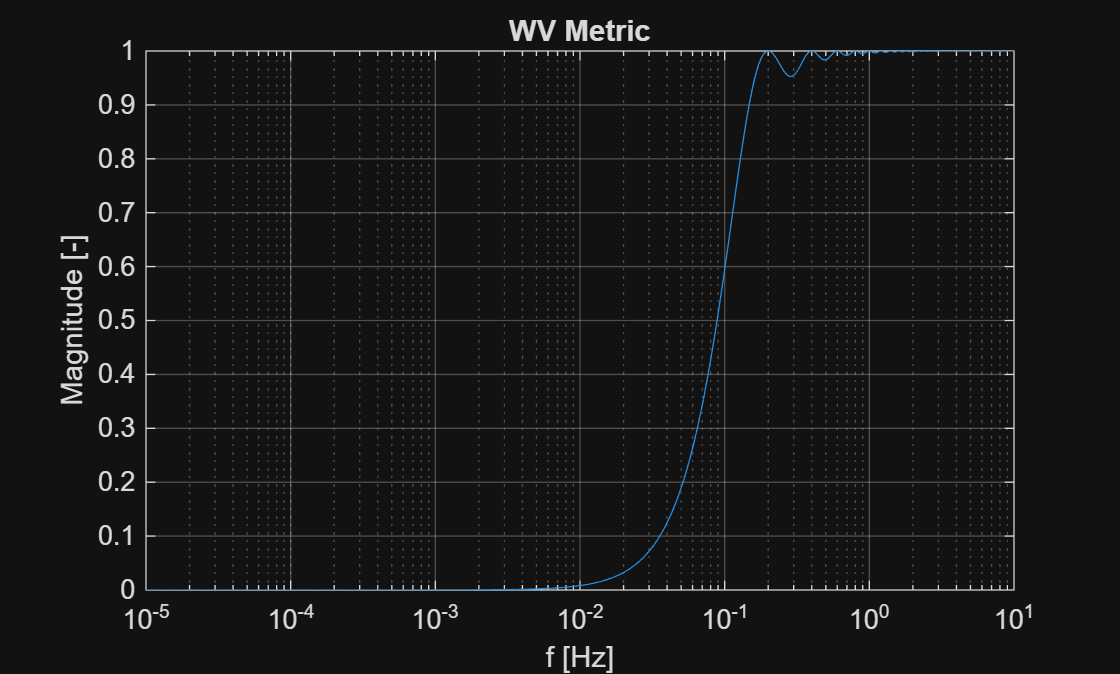

windowDt = 5;		% [s]
%F_WV = (sin(pi * fVec * windowDt) ./ (pi * fVec * windowDt)).^2;   % (nx1 vector)
omegaVec = 2 * pi * fVec;
F_WV = 1 - (sin(omegaVec * windowDt / 2)./(omegaVec * windowDt / 2)).^2;
figure('Name','WV Metric')
semilogx(fVec,F_WV);
title('WV Metric')
xlabel('f [Hz]')
ylabel('Magnitude [-]')
grid on

For the given time window, only frequencies above around 0.05 Hz contribute significantly to the RKE. The integration can be approximated by the trapezoidal rule and yields:

strWvPsd = F_WV .* strPsd;    % 
strWvPsdInt = dot(gradient(fVec), strWvPsd); % = sigma^2_{STR,RKE}

strWvStd = sqrt(strWvPsdInt);  % [rad]

fprintf('STR WV knowl. error:  %g arcsec\nWV knowl. error req.: %g arcsec',strWvStd*rad2arcsec,eWVreq*rad2arcsec);

STR WV knowl. error:  2.37051 arcsec
WV knowl. error req.: 0.5 arcsec

%Str WV knowl. error: 0.75

The STR alone cannot meet the RKE requirement, hence we will now analyze whether adding a gyro will help.

## Gyro Data

The gyro noise is assumed to consist of angular random walk (ARW) and flicker rate (bias instability). The ARW is simply a white noise process on the measured angular rate, i.e. its PSD is a constant. The flicker rate PSD has a 1/f profile, hence the total PSD is

$S_{\mathrm{gyro}}(\omega)=N_{\mathrm{ARW}}^2 +\frac{N_{\mathrm{FR}}^2}{\omega}$,

where the PSD coefficients are taken directly from the datasheet. To compare the gyro noise with the STR noise, it has to be integrated once, i.e. multiplied by 1/s in the frequency domain. Because $s=\mathrm{j}\omega =\mathrm{j}\;2\pi f$, the factor $2\pi \;$must not be forgotten. Furthermore, the PSD is the Fourier transform of the autocorrelation, hence (loosely speaking) it corresponds to the square of the signal of interest. Therefore, the PSD of the integrated angular rate measurement noise is:


$$S_{\mathrm{gyro},\varphi}(\omega)=\frac{N_{\mathrm{ARW}}^2}{\omega^2} +\frac{N_{\mathrm{FR}}^2}{\omega^3}$$


gyroArwCoeff = 0.0016 * pi / 180 / sqrt(3600);	% [rad/sqrt(s)]
gyroFlickerCoeff = 0.01 * pi / 180 / 3600;	% [rad/s]

gyroArwRatePsd = (gyroArwCoeff^2) * ones(size(fVec));  %  (nx1 vector)
gyroFlickerRatePsd = (gyroFlickerCoeff^2) ./ fVec;  %  (nx1 vector)

gyroRatePsd = gyroArwRatePsd + gyroFlickerRatePsd;

gyroAngPsd = gyroRatePsd ./ (2 * pi * fVec).^2;  %  (nx1 vector)

## Plot and Compare Attitude Error PSDs

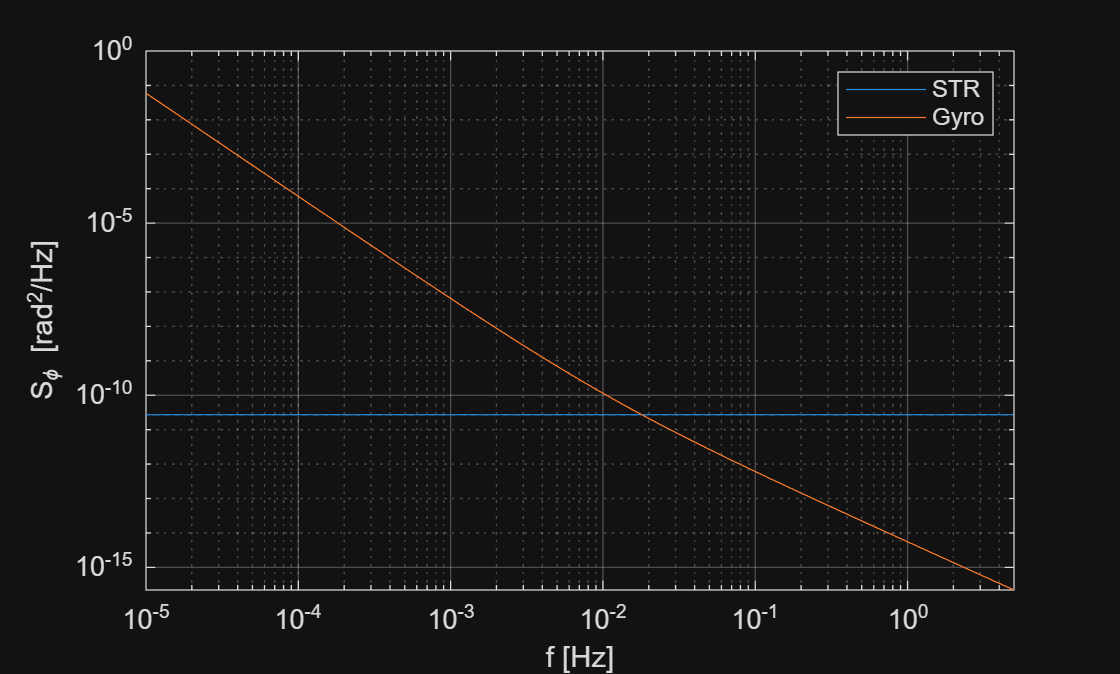

figPsd = figure('Name','Attitude Error PSD');
pStr = loglog(fVec,strPsd);
hold on
pGyro = loglog(fVec,gyroAngPsd);

legend([pStr, pGyro],{'STR','Gyro'})

grid on
xlabel('f [Hz]')
ylabel('S_\phi [rad^2/Hz]')
xlim([fVec(1) 5])

As expected, the gyro is more accurate at higher frequencies. Over time, however, more and more angular rate noise is integrated, causing the measurement to drift and thus a larger noise at low frequencies. From the plot, we can expect the Astrix 120 to improve the attitude knowledge at frequencies above around 0.05 Hz. Remember that this is the relevant frequency range for the RKE!

## Gyro-Stellar Estimator

The gyro-stellar estimator (GSE) can be interpreted as an observer that consists of two complementary filters:


$$\hat{\varphi}(s)	= \frac{k_1\,s - k_2}{s^2 + k_1\,s - k_2}\,\tilde{\varphi}_{\mathrm{STR}}(s) + \frac{s^2}{s^2 + k_1\,s - k_2}\,\frac{1}{s}\,\tilde{\omega}_{\mathrm{Gyro}}(s) = G_1(s)\,\tilde{\varphi}_{\mathrm{STR}}(s) + G_2(s)\,\frac{1}{s}\,\tilde{\omega}_{\mathrm{Gyro}}(s)$$


The attitude estimate $\hat{\varphi}$ consists of the STR measurement $\tilde{\;\varphi \;}$ filtered by the low pass $G_{1\;} \left(s\right)$ and the integrated gyro measurement $\frac{1}{s}\tilde{\;\omega \;}$ filtered by the high pass $G_2 \left(s\right)$. The filters are complementary because $G_1 \left(s\right)+G_2 \left(s\right)=1$. Formulated in terms of damping and natural frequency, the characteristic polynomial of the filters is $s^2 +2\zeta \omega_0 \;s+\omega_0^2$, hence $k_{1\;} =2\;\zeta \omega_0$ and $k_2 =-\omega_0^2$.

One approach to select the filter gains is to define a "fusion frequency" $\omega_{\mathrm{f}}$ where the PSDs of STR and gyro intersect and to demand $|G_1 \left(\mathrm{j}\omega_{\mathrm{f}} \right)|=|G_2 \left(\mathrm{j}\omega_{\mathrm{f}} \right)|$. Choosing $\zeta =1/\sqrt{\;2}$ and solving for the fusion frequency then yields:


$$\omega_0=\frac{\omega_{\mathrm{f}}}{\sqrt{1+\sqrt{2}}} \\
k_1 = \frac{\sqrt{2}\,\omega_{\mathrm{f}}}{\sqrt{1+\sqrt{2}}} \\
k_2 = -\frac{\omega_{\mathrm{f}}^2}{1+\sqrt{2}}$$


Finally, the PSD of the GSE's attitude estimate is computed by:


$$S_{\mathrm{GSE}}(\omega) = |G_1(\mathrm{j}\omega)|^2\,S_{\mathrm{STR}}(\omega) + |G_2(\mathrm{j}\omega)|^2\,S_{\mathrm{gyro},\varphi}(\omega)$$


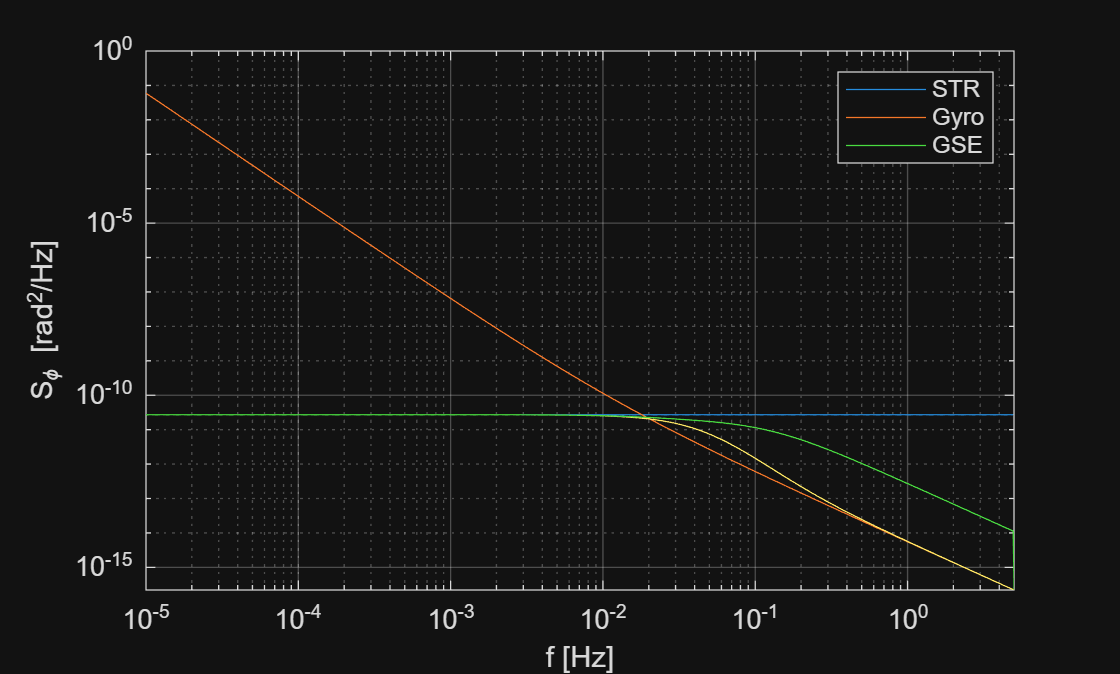

fFusion = 0.05;	% [Hz]

damping = 1; % [-]
om0 = 2 * pi * fFusion;	% [rad/s]
k1 = 2* damping * om0; %
k2 = om0^2;  %

%G1 = tf([],[]); %
%G2 = tf([],[]); %

G1 = tf([k1, -k2],[1, k1, -k2]);     % Low-pass filter (STR)
G2 = tf([1, 0, 0],[1, k1, -k2]);   % High-pass filter (Gyro)

G1fr = squeeze(freqresp(G1,fVec,'Hz'));
G1mag = abs(G1fr);

G2fr = squeeze(freqresp(G2,fVec,'Hz'));
G2mag = abs(G2fr);

gseAttPsd = G1mag.^2.*strPsd(:,1) + G2mag.^2.*gyroAngPsd;

figure(figPsd)
pGse = loglog(fVec,gseAttPsd);

legend([pStr,pGyro,pGse],{'STR','Gyro','GSE'});

As expected, the PSD of the GSE follows the STR for low frequencies and it follows the gyro for high frequencies.

## Compare PSDs of RKE

We can now approximate the achievable AKE and RKE and compare them with the STR:

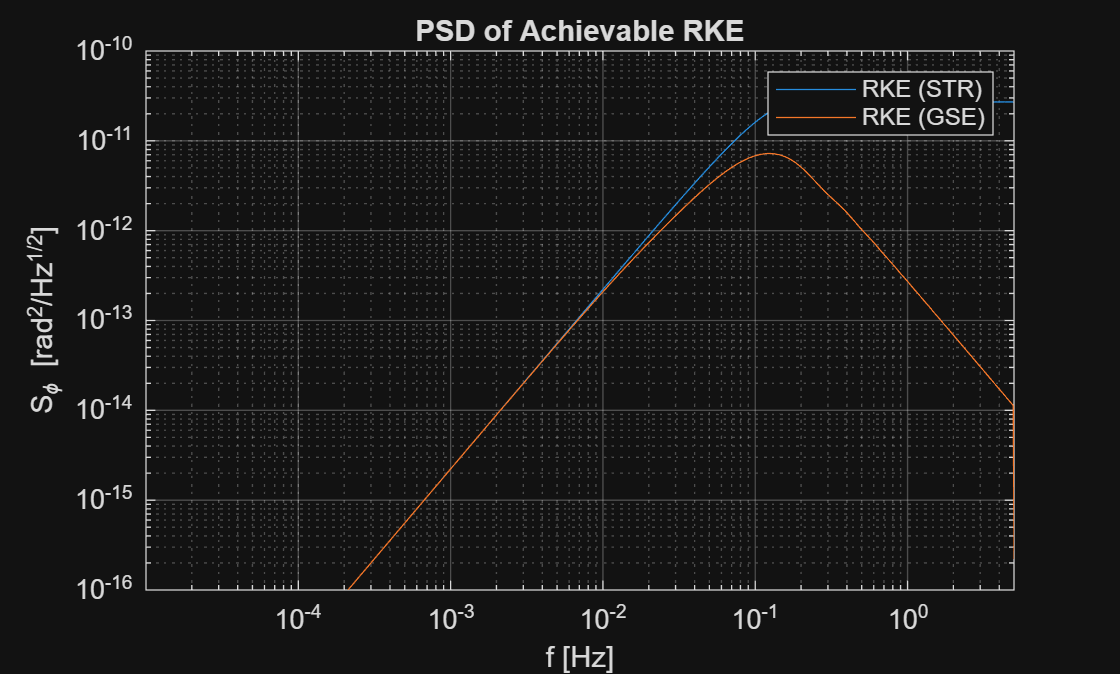

gsePsdInt = trapz(fVec, gseAttPsd); %dot(gradient(...))
gseAbsStd = sqrt(gsePsdInt);       % [rad]
gseWvPsd = F_WV .* gseAttPsd;
gseWvPsdInt = trapz(fVec, gseWvPsd);

gseWvStd = sqrt(gseWvPsdInt);	% [rad]

figPsdP = figure('Name','Pointing Error PSDs');
pStrWv = loglog(fVec,strWvPsd);
hold on
pGseWv = loglog(fVec,gseWvPsd);

legend([pStrWv,pGseWv],{'RKE (STR)' 'RKE (GSE)'});
title('PSD of Achievable RKE')
xlabel('f [Hz]')
ylabel('S_\phi [rad^2/Hz^{1/2}]')
ylim([1e-16, 1e-10]);
xlim([1e-5,5]);
grid on

fprintf('ABS requirement: %g arcsec\nApprox. ABS std of STR: %g arcsec\nApprox. ABS std of GSE: %g arcsec\n',eABSreq*rad2arcsec	,strAbs*rad2arcsec,gseAbsStd*rad2arcsec);

ABS requirement: 1 arcsec
Approx. ABS std of STR: 2.4 arcsec
Approx. ABS std of GSE: 0.400635 arcsec


fprintf('WV requirement: %g arcsec\nApprox. WV std of STR: %g arcsec\nApprox. WV std of GSE: %g arcsec\n',eWVreq*rad2arcsec,strWvStd*rad2arcsec,gseWvStd*rad2arcsec);

WV requirement: 0.5 arcsec
Approx. WV std of STR: 2.37051 arcsec
Approx. WV std of GSE: 0.302966 arcsec
